We have the next problem

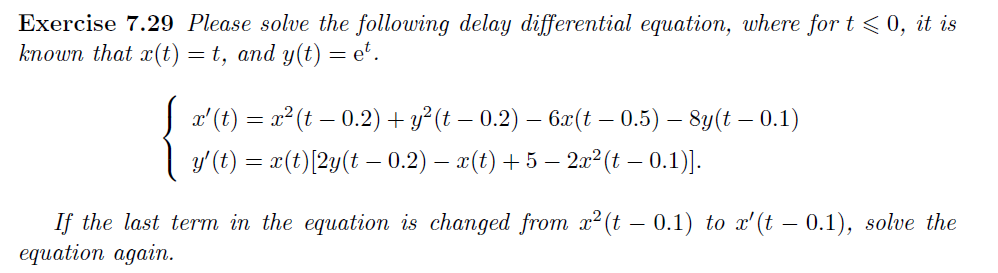

We start define our state equation


$$x(1) = x(t), \;\;\;\; x(2) = y(t);$$


And, for delay equation.


$$z(1,\;) = x(t-a_i) \;\;\;\; z(2,\;) = y(t-a_j)$$


When $a_i$ and $a_j$ are delays. Now, we write the equations

f=@(t,x,Z)[(Z(1,1)).^2+(Z(2,1)).^2-6*Z(1,2)-8*Z(2,3);...
           x(1)*(2*(Z(2,1))-x(1)+5-2*(Z(1,3)).^2)]

f = function_handle with value:
    @(t,x,Z)[(Z(1,1)).^2+(Z(2,1)).^2-6*Z(1,2)-8*Z(2,3);x(1)*(2*(Z(2,1))-x(1)+5-2*(Z(1,3)).^2)]


We introduce lags

lags=[0.2; 0.5; 0.1]

lags =     0.2000
    0.5000
    0.1000


The history for this equations are


$$x_\textrm{history}=t\;\;\;\; y_\textrm{history} = e^t$$


history=@(t)[t; exp(t)]

history = function_handle with value:
    @(t)[t;exp(t)]


We define time interval

rvt=linspace(0,0.9,2^5)

rvt =          0    0.0290    0.0581    0.0871    0.1161    0.1452    0.1742    0.2032    0.2323    0.2613    0.2903    0.3194    0.3484    0.3774    0.4065    0.4355    0.4645    0.4935    0.5226    0.5516    0.5806    0.6097    0.6387    0.6677    0.6968    0.7258    0.7548    0.7839    0.8129    0.8419    0.8710    0.9000


Finally, the algoritm is

sol=dde23(f,lags,history,rvt)

sol = struct with fields:
     solver: 'dde23'
    history: @(t)[t;exp(t)]
    discont: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000]
          x: [1×41 double]
          y: [2×41 double]
      stats: [1×1 struct]
         yp: [2×41 double]


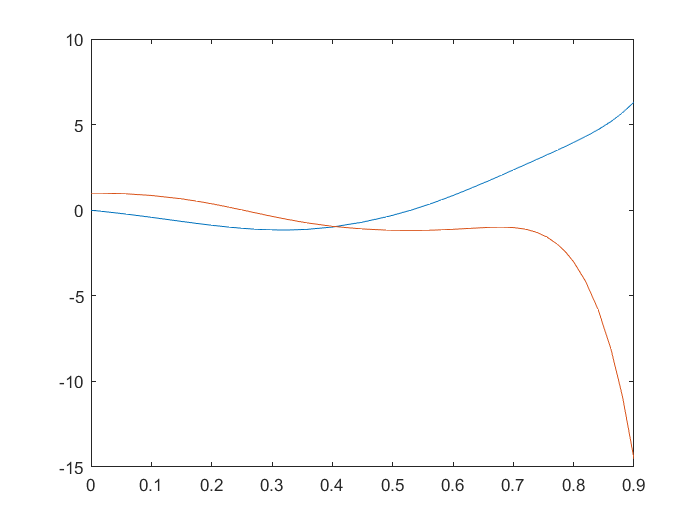

plot(sol.x,sol.y)

we plot the result 

Changed the equation, we have now


$$x\prime = x^2(t-0.2) + y^2(t-0.2) - 6x(t-0.5) - 8y(t-0.1)$$



$$y\prime (t) = x(t)[2y(t-0.2)-x(t)+5-2x\prime(t-0.1)]$$


We will solutionate this equation using ddensd algoritm, if we want to know more about this algoritm, we can visit matlab documentation

We start defining the states equation, so


$$x(1) = x(t), \;\;\;\; x(2) = y(t)$$


In addition, dalay equation will are


$$z1 \to \textrm{Delay of state equation}\;\;\;\; z2 \to \textrm{Delay of derivaties of state equation} $$


So, we writte the equation in code as

f=@(t,x,z1,z2)[z1(1,1)+(z1(2,1))^2-6*z1(1,2)-8*z1(1,3);...
               x(1)*(2*z1(2,1)-x(1)+5-2*z2(1,1))]

f = function_handle with value:
    @(t,x,z1,z2)[z1(1,1)+(z1(2,1))^2-6*z1(1,2)-8*z1(1,3);x(1)*(2*z1(2,1)-x(1)+5-2*z2(1,1))]


Now, we define the delays and history equations

dy=[0.2;0.5;0.1]

dy =     0.2000
    0.5000
    0.1000


dyp=[0.1]

dyp = 0.1000

history=@(t)[t; exp(t)]

history = function_handle with value:
    @(t)[t;exp(t)]


rvt=linspace(0,2,2^7)

rvt =          0    0.0157    0.0315    0.0472    0.0630    0.0787    0.0945    0.1102    0.1260    0.1417    0.1575    0.1732    0.1890    0.2047    0.2205    0.2362    0.2520    0.2677    0.2835    0.2992    0.3150    0.3307    0.3465    0.3622    0.3780    0.3937    0.4094    0.4252    0.4409    0.4567    0.4724    0.4882    0.5039    0.5197    0.5354    0.5512    0.5669    0.5827    0.5984    0.6142    0.6299    0.6457    0.6614    0.6772    0.6929    0.7087    0.7244    0.7402    0.7559    0.7717


We solucionate the system

sol=ddensd(f,dy,dyp,history,rvt)

sol = struct with fields:
     solver: 'ddensd'
    history: @(t)[t;exp(t)]
          x: [1×84 double]
          y: [2×84 double]
      stats: [1×1 struct]
         yp: [2×84 double]
        IVP: 0


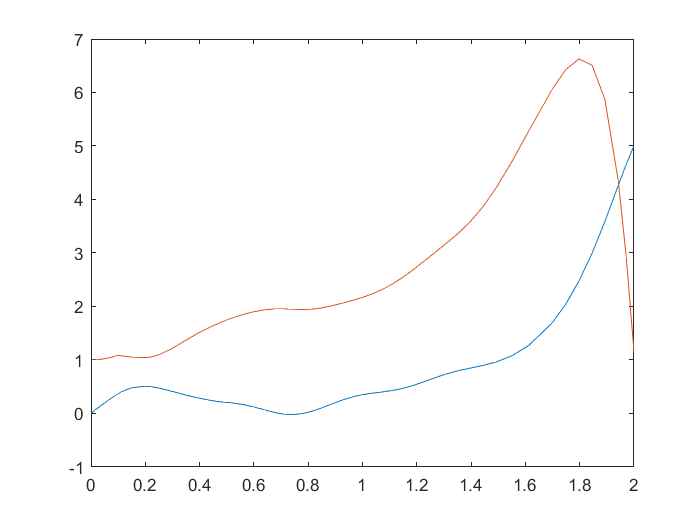

plot(sol.x,sol.y)